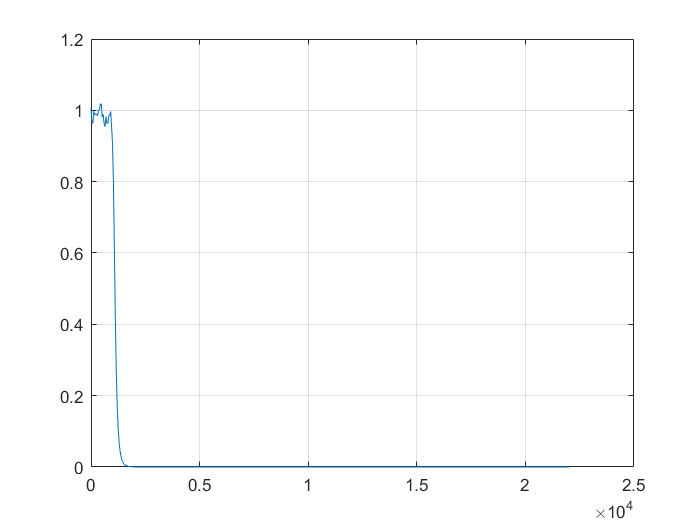

clear sound
timestart = 0;

[audio, fs] = audioread ('ech22.wav');% sound reading
audio = audio (:, 1);% dual channel to single channel
n = length (audio);
T = 1 / fs;% sampling interval
t = (0: n-1) * T;% time axis
f = (0: n-1) / n * fs;% frequency axis

% Fast Fourier Transform
audio_fft = fft (audio, n) * T;
timeend = t;
wlen = 20480;% sets the window length. The longer the window, the worse the resolution, and the better the frequency resolution.
hop = 2000;% The step size of each translation, the minimum is 1. The smaller the image, the better the time accuracy, but the amount of calculation is large.
audio_fft = wkeep1 (audio_fft, n + 1 * wlen);% intermediate truncation

% Design IIR low-pass filter
rp = 1;
rs = 60;
Ft = fs;
Fp = 500;
Fs = 900;
wp = 2 * pi * Fp / Ft;
ws = 2 * pi * Fs / Ft;% find the boundary frequency of the analog filter to be designed
[N, wn] = buttord (wp, ws, rp, rs, 's');% low-pass filter order and cutoff frequency
[b, a] = butter (N, wn, 's'); %The parameters of the frequency response in the S domain are: the transfer function of the filter
[bz, az] = bilinear (b, a, 0.5);% Using bilinear transformation to realize the transformation from frequency domain S domain to Z domain
figure (2);% low-pass filter characteristics
[h, w] = freqz (bz, az);
title ('IIR low-pass filter');
plot (w * fs / (2 * pi), abs (h));
grid;

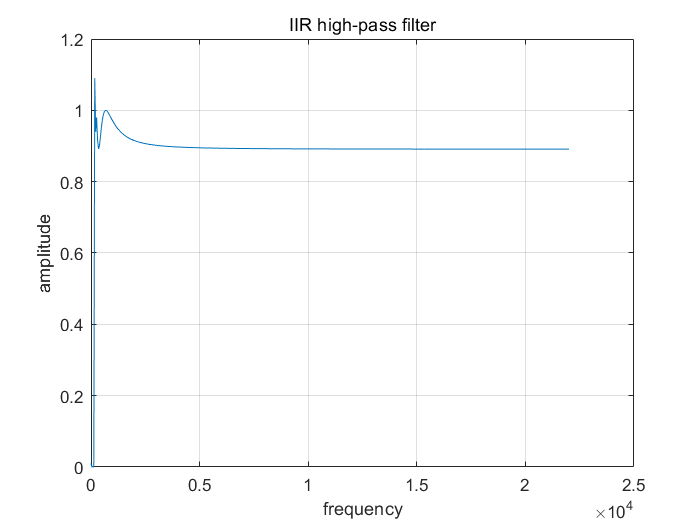


% Design IIR high-pass filter
Fp = 150;
Fs1 = 240;
Ft = fs;
As = 100;
Ap = 1;
wp = 2 * pi * Fp / Ft;
ws = 2 * pi * Fs1 / Ft;
[n, wn] = ellipord (wp, ws, Ap, As, 's');
[b, a] = ellip (n, Ap, As, wn, 'high', 's');
[B, A] = bilinear (b, a, 1);
[h, w] = freqz (B, A);
figure (4);
plot (w * Ft / pi / 2, abs (h));
title ('IIR high-pass filter');
xlabel ('frequency');
ylabel ('amplitude');
grid on;

% Filtering
z = filter (bz, az, audio);
z = filter (B, A, z);
z_fft = fft (z);% filtered signal spectrum

sound (z, fs);% playback

% Do Short Time Fourier
h = hamming (wlen);% set the window length of Hamming window
f = 220: 1: 500;% set frequency scale

[tfr2, f, t2] = spectrogram (z, h, wlen-hop, f, fs, 'MinThreshold',-1000, 'reassigned', 'yaxis');% spectrum
axis xy;

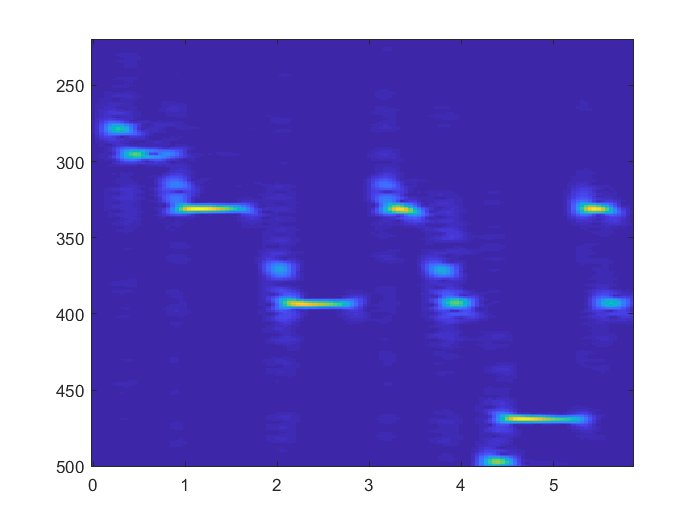

tfr2 = tfr2 * 2 / wlen * 2;
figure
imagesc (t2 + timestart-wlen / fs / 2, f, abs (tfr2))% change of each frequency

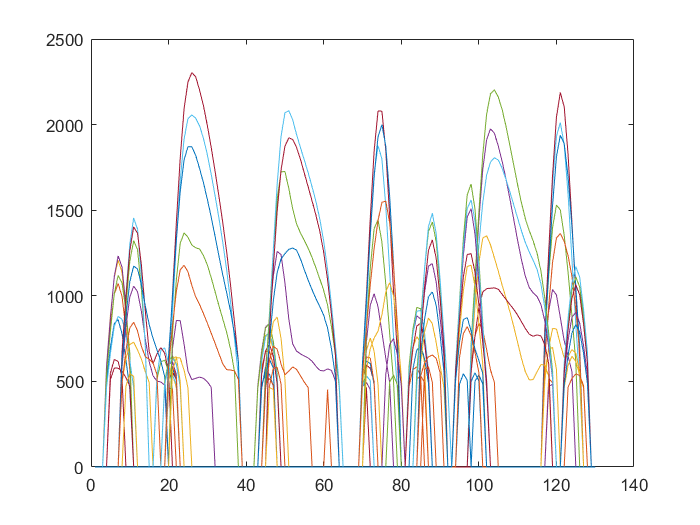


shi = abs (tfr2);

clims = [50 100];

shi = shi.* 10000;
shi (shi <450) = 0;
plot (shi');

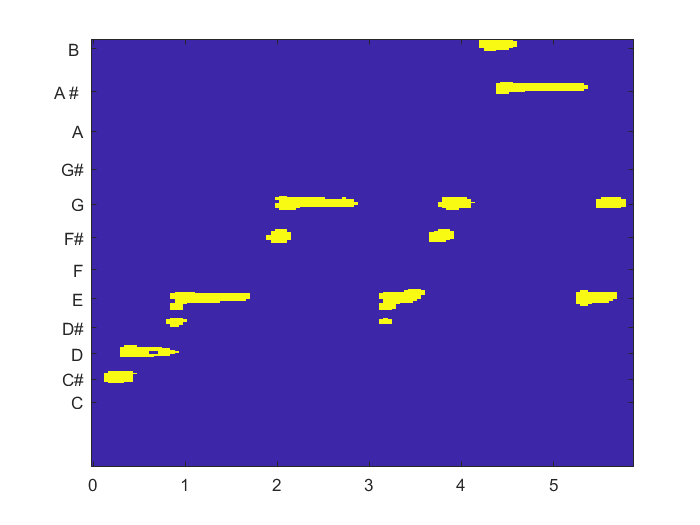

imagesc (t2 + timestart-wlen / fs / 2, f, shi, clims);
axis xy;
set (gca, 'ytick', [262 277 294 311 330 349 370 392 415 440 466 494]);
set (gca, 'yticklabel', {'C', 'C#', 'D', 'D#', 'E', 'F', 'F#', 'G', 'G#', 'A', ' A # ',' B '});% annotation